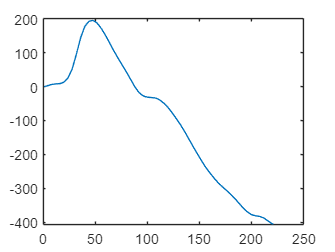

i1 = 3;
i2 = 3;
if (length(CYCLE_DATA_INH{i1}.RHEO2) > length(CYCLE_DATA_INH{i2}.RHEO2))
    data_temp1 = CYCLE_DATA_INH{i2}.RHEO2;
    data_temp2 = CYCLE_DATA_INH{i1}.RHEO2(1:length(CYCLE_DATA_INH{i2}.RHEO2));
else
    data_temp1 = CYCLE_DATA_INH{i1}.RHEO2;
    data_temp2 = CYCLE_DATA_INH{i2}.RHEO2(1:length(CYCLE_DATA_INH{i1}.RHEO2));
end
max(xcorr(data_temp1,data_temp2,'normalized'));
plot(-CYCLE_DATA_INH{i1}.RHEO1);

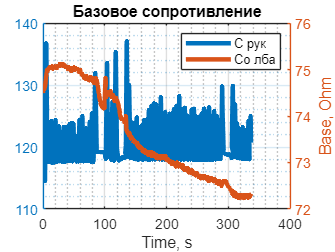

yyaxis left
plot(DATA.TIME,DATA.BASE1,'LineWidth',3);
yyaxis right
plot(DATA.TIME,DATA.BASE2,'LineWidth',3);
title("Базовое сопротивление")
legend(["С рук","Со лба"]);
ylabel('Base, Ohm') 
xlabel('Time, s')
grid on
grid minor

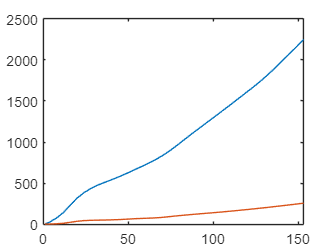

ii=3;
i1 = 1;
i2 = 4;
% if (length(CYCLE_DATA_EXH{i1}.RHEO2) > length(CYCLE_DATA_EXH{i2}.RHEO2))
%     data_temp1 = CYCLE_DATA_EXH{i2}.RHEO2;
%     data_temp2 = CYCLE_DATA_EXH{i1}.RHEO2(1:length(CYCLE_DATA_EXH{i2}.RHEO2));
% else
%     data_temp1 = CYCLE_DATA_EXH{i1}.RHEO2;
%     data_temp2 = CYCLE_DATA_EXH{i2}.RHEO2(1:length(CYCLE_DATA_EXH{i1}.RHEO2));
% end
% max(xcorr(data_temp1,data_temp2,'normalized'));
if (~isempty(FORM_EXH{ii}{i1}.RHEO1))
plot(-FORM_EXH{ii}{i1}.RHEO1);
hold on
plot(-FORM_EXH{ii}{i1}.RHEO2);
hold off
end

FORM_EXH{ii}{i1}.NAME

ans = datetime
   21-Nov-2024 11:17:00


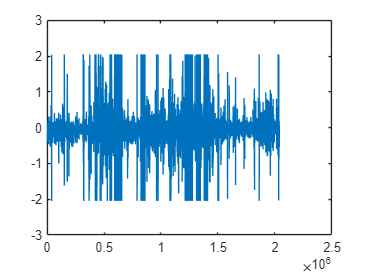

plot(SIGNAL)

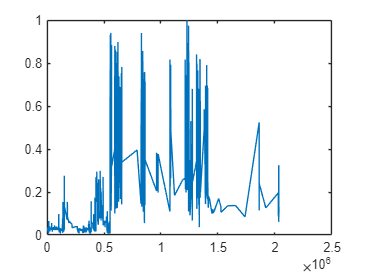

plot(qrs_i_raw,qrs_amp_raw)

DATA_CL(abs(DATA_CL.ECG)<0.5,:)

ans = 1082964×11 table
            DATE            TIME      ECG      RHEO1     BASE1     QS1      RHEO2     BASE2     QS2     MEAN_b1    MEAN_b2
    ____________________    _____    _____    _______    ______    ____    _______    ______    ____    _______    _______

    20-Feb-2025 08:17:21        0    0.233    -16.423    66.686    1363     -9.462    76.012    1662    66.479     74.763 
    20-Feb-2025 08:17:21    0.005    0.232    -20.883    66.685    1363     -9.358    76.011    1662    66.479     74.763 
    20-Feb-2025 08:17:21     0.01    0.232    -25.344    66.684    1363     -9.255    76.011    1662    66.479